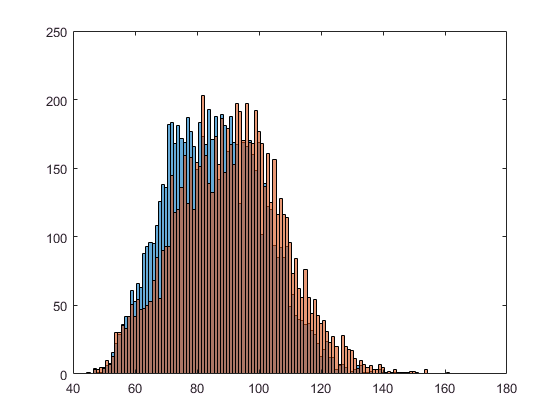

load waistmeasure.mat
histogram(waist(:,1),'BinMethod','integer')
hold on
histogram(waist(:,2),'BinMethod','integer')
hold off


mu = mean(waist)

mu =    85.9192   90.4684

sigma = std(waist)

sigma =    15.5576   16.9444


W = (40:160)';

D = (1/sqrt(2*pi))./sigma

D =     0.0256    0.0235


P = exp(-1 * (W - mu).^2 ./ (2 * sigma.^2)).*D

P =     0.0003    0.0003
    0.0004    0.0003
    0.0005    0.0004
    0.0006    0.0005
    0.0007    0.0005
    0.0008    0.0006
    0.0010    0.0008
    0.0011    0.0009
    0.0013    0.0010
    0.0015    0.0012


plot(W,P)
xlabel('waist size')
ylabel('fraction of people')
legend('1999','2009')

